clearvars;

% Global constants
global kb q0 me T0 ne_0 CO2 O T_Ke T_Ki T_Je T_Ji T_Ee T_Ei O2p_0 CO2p_0 Op_0 v1 k2 v3 k4 k5 k6 k7 k8 k9 k10
global e1 e2 e3 e4 e5 e6 e7 e8 e9 e10 s1 s2 s3
e1 = 1;
e2 = 1;
e3 = 0;
e4 = 0;
e5 = 0;
e6 = 1;
e7 = 0;
e8 = 1;
e9 = 1;
e10= 0;

s1 = 1; % CO2p
s2 = 0; % O2p
s3 = 0; % Op


kb = 1.3806e-23;
q0 = 1.602e-19;
me = 9.109e-31;
T0 = 2.5e-4;

n = 301; % number of lines in profile

fName1 = 'input/Profiles.in';
fid1 = fopen(fName1,'r');
if fid1 == -1
    disp("File "+fName1+" doesn't currently exist in "+pwd);
    return;
end
for i=1:n
    line1(i,:) = textscan(fid1,'%f %f %f %f %f %f %f %f %f %f %f %f %f %f %f %f %f %f',1, 'headerlines',1);
end

fName2 = 'input/Partition.in';
fid2 = fopen(fName2,'r');
if fid2 == -1
    disp("File "+fName2+" doesn't currently exist in "+pwd);
    return;
end
for i=1:n
    line2(i,:) = textscan(fid2,'%f %f %f %f',1, 'headerlines',1);
end

% Convert to matrices
line1 = cell2mat(line1);
line2 = cell2mat(line2);

% Remove unrelated data
line1(:,12:18) = [];
line1(:,8) = [];
line1(:,2:5) = [];

% Updates units
line1(:,1) = line1(:,1)./1e3; % m -> km
line2(:,1) = line2(:,1)./1e3; % m -> km
line1(:,2) = line1(:,2)./1e6; % m-3 -> cm-3
line1(:,3) = line1(:,3)./1e6; % m-3 -> cm-3
line1(:,4) = line1(:,4)./1e6; % m-3 -> cm-3

fclose(fid1);
fclose(fid2);

badi = [];
numsolved = 0;
numskipped = 0;
data = zeros(n,4);
skip = 20;
for i=1:n
    alt  = line1(i,1);
    O    = line1(i,2);
    CO2  = line1(i,3);
    ne_0 = line1(i,4);
    T_Ke = line1(i,5);
    T_Ki = line1(i,6);
    
    T_Je = T_Ke*kb;
    T_Ji = T_Ki*kb;
    
    T_Ee = T_Je/q0;
    T_Ei = T_Ji/q0;
    
    O2p_0  = line2(i,2)*ne_0;
    CO2p_0 = line2(i,3)*ne_0;
    Op_0   = line2(i,4)*ne_0;
    ne_0   = O2p_0 + CO2p_0 + Op_0;
    
    
    % Reaction constants
    v1 = 5e-7; % 1/s
    k2 = 0;                            %  Itikawa2002 has no Xsec for E < 1eV
    v3 = 2e-7; % 1/s
    k4 = 9e-9*T_Ee^0.7*exp(-13.6/T_Ee); %  This is way too low
    
    if (T_Ke<1200)
        k5 = 1.95e-7*(300/T_Ke)^0.7;
    else
        k5 = 7.38e-8*(1200/T_Ke)^0.56;
    end
    
    k6 = 3.1e-7*sqrt(300/T_Ke);
    k7 = 3.7e-12*(250/T_Ke)^0.7;
    k8 = 1.64e-10;
    k9 = 9.6e-11;
    
    if (T_Ke>800)
        k10 = 1.1e-9;
    else
        k10 = 1.1e-9*(800/T_Ki)^0.39;  % cm^-3/s
    end
   
    %x0 = [CO2p_0, O2p_0, Op_0, ne_0];
    %[sol,~,exitflag] = fsolve(@SOE,x0);
    
    %x0 = [O2p_0, ne_0];
    %[sol,~,exitflag] = fsolve(@SOE5810,x0);
    
    if (mod(i,skip) == 0)
        x0 = [CO2p_0, O2p_0, Op_0, ne_0];
        [sol,~,exitflag] = fsolve(@SOEall,x0);
        if (exitflag >= 0)
            data(i,:) = sol(:);
            numsolved = numsolved + 1;
        else
            data(i,:) = zeros(1,4);
            badi = [badi,i];
            numskipped = numskipped + 1;
        end
    else
        badi = [badi,i];
    end
end


Solver stopped prematurely.

fsolve stopped because it exceeded the iteration limit,
options.MaxIterations = 4.000000e+02.


Solver stopped prematurely.

fsolve stopped because it exceeded the iteration limit,
options.MaxIterations = 4.000000e+02.


Solver stopped prematurely.

fsolve stopped because it exceeded the iteration limit,
options.MaxIterations = 4.000000e+02.


Solver stopped prematurely.

fsolve stopped because it exceeded the iteration

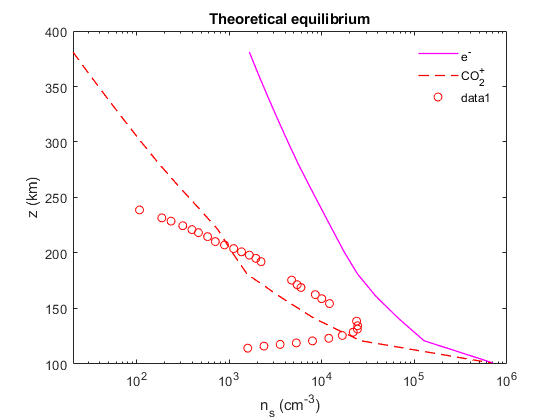

tempdata = data;
Z = line1(:,1);

for i=length(badi):-1:1
    tempdata(badi(i),:) = [];
    Z(badi(i)) = [];
end

semilogx(tempdata(:,4),Z,'DisplayName','e^-','LineWidth',1,'Color','m','LineStyle','-');
hold on;
if s1
    semilogx(tempdata(:,1),Z,'DisplayName','CO_2^+','LineWidth',1,'Color','r','LineStyle','--');
end
if s2
    semilogx(tempdata(:,2),Z,'DisplayName','O_2^+','LineWidth',1,'Color','k','LineStyle','-.');
end
if s3
    semilogx(tempdata(:,3),Z,'DisplayName','O^+','LineWidth',1,'Color','b','LineStyle',':');
end

%%%%%%CHECK WITH THEORETICAL%%%%%%%%

tempCO2 = [107.28443014544911, 238.81087784813934,186.81809528372952, 231.66782071435557,234.7542544916016, 228.73721448609507,314.6875438309644, 224.59740261321213,395.03062258963615, 221.05560394575534,464.5663141383297, 218.36082281080465,583.1088976231371, 214.75111387232602,706.8980779994838, 210.28593692918963,888.1486408313958, 207.26478367290005,1115.366197275364, 203.97198933252324,1355.6298531130644, 201.0461118658813,1647.6492681422417, 198.12023439923934,1936.9460712938242, 195.19908569421594,2202.083207554452, 192.19211872278197,4713.658420891596, 175.60064559651647,5408.092713513752, 171.41499100683157,5952.282040476774, 168.95603496519067,8496.361932707108, 162.52045311133625,9975.335409790083, 158.82965466806564,12094.845277034583, 154.45502475295834,23717.072856163344, 138.60053788190828,24352.137742153875, 134.46686464216347,24228.71247608603, 131.42448450038623,21823.663513818727, 128.6950958359606,16631.980222543043, 125.6769637329273,11868.059507423008, 123.16629780729107,7924.805887082224, 120.82354670394281,5296.532173844187, 119.02407776876905,3542.6070491965934, 117.67734397374073,2368.7705537823995, 116.14951612265423,1582.9248605572204, 114.25950015945139];
j = 1;
while j <= length(tempCO2)-1
    tempCO2x(ceil(j/2)) = tempCO2(j);
    tempCO2y(ceil(j/2)) = tempCO2(j+1);
    j = j+2;
end
tempO2 = [30716.31948711234, 113.83864037540133,47152.29831133881, 115.02766121348537,68868.39878425805, 118.34304852603967,90537.83835885575, 122.50056406510558,101597.60708683495, 124.98993596851514,101130.9232323651, 128.88503442763863,89302.21869106576, 134.22811472222295,81336.75599658009, 138.15393261793503,73250.23190306373, 141.97267033388505,63079.59146276196, 145.59398225226101,55546.61432835882, 149.26948811397637,50646.90116378556, 153.84422637723023,41837.88091825807, 159.1696000866429,37986.97917918481, 161.22109450215294,32362.254713340222, 165.0477134874672,27139.47268453116, 169.41997902176522,22749.762040949743, 173.53418552618035,20721.028505316535, 177.4735854760968,17636.859602341927, 180.75692229323653,15534.459851840646, 184.57881251693226,13708.773140758605, 189.54159529379444,9703.790463509347, 202.17059386483822,6779.688133550657, 206.9763292141691,5580.6283729526585, 210.1738477648983,4758.261881010145, 214.49847540437253,4190.103243889844, 218.18454508602463,3456.6103834335577, 222.69499554317554,2752.6528624501793, 226.0330633975669,2268.559894104719, 229.9549581725288,1998.7409193875378, 233.95794245228268,1645.9889733005732, 237.42710208709912];
j = 1;
while j <= length(tempO2)-1
    tempO2x(ceil(j/2)) = tempO2(j);
    tempO2y(ceil(j/2)) = tempO2(j+1);
    j = j+2;
end
tempO = [0.7937273274502612, 114.7491021262895,1.2100019186430861, 115.76702936344202,1.737870386168309, 117.01983594158062,2.64942610966869, 118.06492728714184,3.95994441352583, 119.23056702611197,5.921386363699842, 120.66784784916939,8.85771906416737, 122.33149624229952,13.24312670265674, 123.67823003732786,19.817699092943634, 125.56824600053068,29.678661595817765, 127.91099710387894,43.001413018341694, 130.4214616192981,60.30030820122635, 133.30789771125504,79.17156352437125, 136.69274527780613,94.01334775449823, 139.79297393671683,108.07692789910513, 143.4412135254206,120.14537647205104, 146.95836133369926,133.53115884527594, 150.33968859993433,145.9623927163447, 157.0744084109912,138.62657488932382, 152.8068937035098,155.82177194156677, 162.95208396351745,167.84926762636397, 167.5605248697637,174.40449980667086, 170.54384803310495,187.35565564568742, 173.52244243482767,208.79714372426574, 178.5336162055862,228.3734529267478, 185.63052412875942,217.09925658178955, 181.92440099505836,259.67559788477456, 189.37088699936515,289.21857173008755, 194.01987265800736,355.26075127163136, 197.43228715340135,436.38346126634383, 200.8447016487953,501.7764469216845, 204.6287617795427,570.8816677876953, 210.04455991946105,606.6152466081313, 218.45881325989996,602.2278199242932, 214.11255591450387,675.4503379316304, 222.9493416194913,805.1412358876071, 228.3358827361364,925.7933548660269, 232.11994286688378,1100.3438459377821, 235.76345369396898,1305.7293536175819, 238.45622072674882];
j = 1;
while j <= length(tempO)-1
    tempOx(ceil(j/2)) = tempO(j);
    tempOy(ceil(j/2)) = tempO(j+1);
    j = j+2;
end
%semilogx(tempOx,tempOy,    'o','Color','b');
%semilogx(tempO2x,tempO2y,  'o','Color','k');
semilogx(tempCO2x,tempCO2y,'o','Color','r');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%






hold off;
legend('show','Location','northeast');
legend boxoff;
title('Theoretical equilibrium');
xlabel("n_s (cm^-^3)");
ylabel("z (km)");
xlim([0,10^6]);
ylim([100 400]);


disp("Points maximum    = "+n);

Points maximum    = 301


disp("Points attempted  = "+(numsolved+numskipped));

Points attempted  = 15


disp("Points successful = "+numsolved);

Points successful = 15


disp("Points failed     = "+numskipped);

Points failed     = 0


function F = SOEall(x)
    global v1 k2 v3 k4 k5 k6 k7 k8 k9 k10 CO2 O CO2p_0 O2p_0 Op_0
    global e1 e2 e3 e4 e5 e6 e7 e8 e9 e10 s1 s2 s3
    
    CO2p = x(1);
    O2p  = x(2);
    Op   = x(3);
    ne   = x(4);
    
    if s1==0
        CO2p = CO2p_0;
    end
    if s2==0
        O2p = O2p_0;
    end
    if s3==0
        Op = Op_0;
    end
    
    R = zeros(1,10);
    if e1
        R(1) = v1*CO2;
    end
    if e2
        R(2) = k2*CO2*ne;
    end
    if e3
        R(3) = v3*O;
    end
    if e4
        R(4) = k4*O*ne;
    end
    if e5
        R(5) = k5*O2p*ne;
    end
    if e6
        R(6) = k6*CO2p*ne;
    end
    if e7
        R(7) = k7*Op*ne;
    end
    if e8
        R(8) = k8*CO2p*O;
    end
    if e9
        R(9) = k9*CO2p*O;
    end
    if e10
        R(10) = k10*Op*CO2;
    end
    
    test11 = 2.7e-10*CO2p*1e10/1e6;
    %https://core.ac.uk/download/pdf/33049209.pdf
    
    %R(1) = 0;
    %R(2) = 0;
    %R(6) = 0;
    %R(8) = 0;
    %R(9) = 0;
    %test11= 0;
    
    
    CO2p_S = R(1) + R(2);
    CO2p_L = R(6) + R(8) + R(9) + test11;
    
    O2p_S  = R(8) + R(10);
    O2p_L  = R(5);

    Op_S   = R(3) + R(4) + R(9);
    Op_L   = R(7) + R(10);
    
    F = [s1*(CO2p_S - CO2p_L),...
         s2*(O2p_S  - O2p_L),...
         s3*(Op_S   - Op_L),...
         ne - (CO2p + O2p + Op)];
end